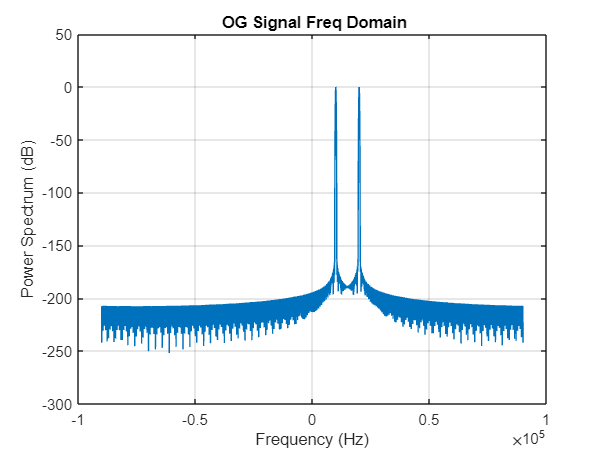

% Sample rate
clear
Fs = 180e3; % 180 kHz
L=10;

% Generate a sample signal (replace this with your actual signal)
t = 0:1/Fs:1-1/Fs; % 1 second of data

f1 = 10e3; % 10 kHz tone
f2 = 20e3; % -10 kHz tone
signal = exp(1j*2*pi*f1*t) + exp(1j*2*pi*f2*t); % Complex signal

% Zero-padding
padFactor = L; % Adjust this factor to get more or less padding
paddedSignal = [signal, zeros(1, length(signal)*(padFactor-1))];

stuffedSignal=upsample(signal,L);
stuffedFiltered=lowpass(stuffedSignal,Fs/2,L*Fs);
% New sample rate remains the same
newFs = Fs*L;

% Plot the spectrum
figure
[pxx,f] = pspectrum(signal,Fs);
plot(f,pow2db(pxx))
grid on
title(' OG Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

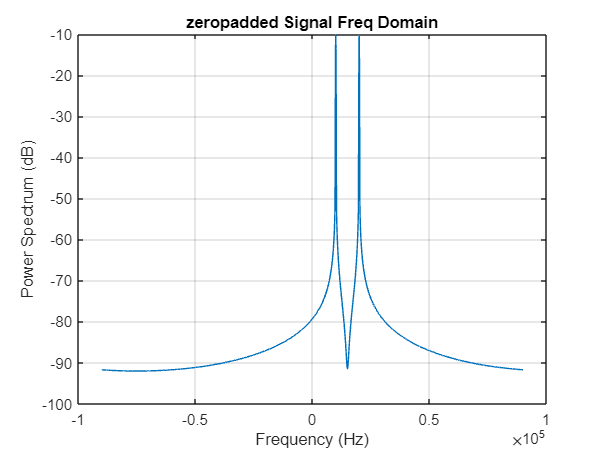

figure
[pxx,f] = pspectrum(paddedSignal,Fs);
plot(f,pow2db(pxx))
grid on
title('zeropadded Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

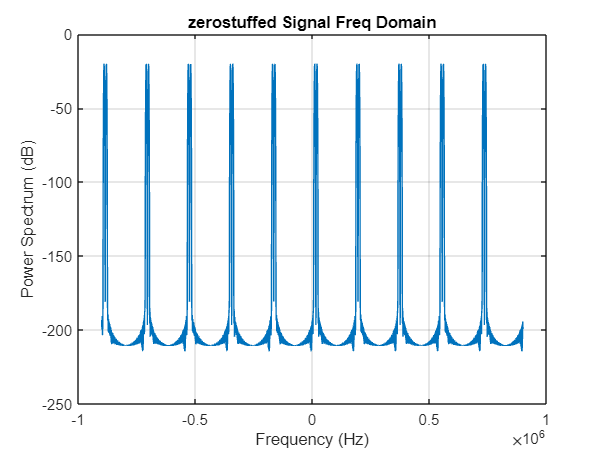

figure
[pxx,f] = pspectrum(stuffedSignal,newFs);
plot(f,pow2db(pxx))
grid on
title('zerostuffed Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

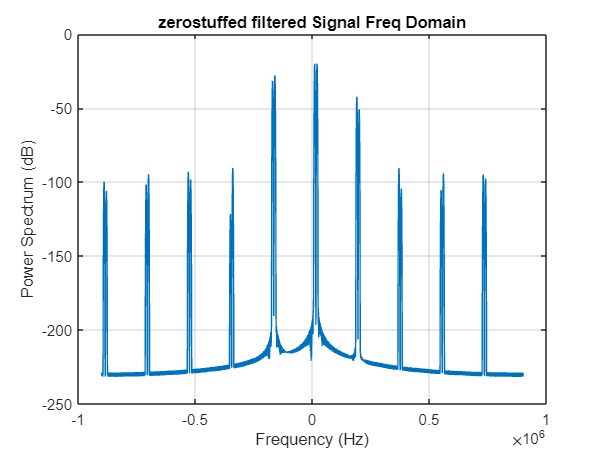

figure
[pxx,f] = pspectrum(stuffedFiltered,newFs);
plot(f,pow2db(pxx))
grid on
title('zerostuffed filtered Signal Freq Domain');
xlabel('Frequency (Hz)')
%xlim([-Fs/2, Fs/2])
ylabel('Power Spectrum (dB)')


%apply doppler

dopplerEffect = exp(1i * 2 * pi * 10e3* t);

Unrecognized function or variable 't'.

dopplerSignal=(signal) .* dopplerEffect;

[pxx,f] = pspectrum(dopplerSignal,Fs);
plot(f,pow2db(pxx))
grid on
title('doppler OG Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

t2 = 0:1/newFs:1-(1/newFs);
dopplerEffect2 = exp(1i * 2 * pi * 10e3* t2);
dopplerSignal2=(stuffedFiltered) .* (dopplerEffect2);

[pxx,f] = pspectrum(dopplerSignal2,newFs);
plot(f,pow2db(pxx))
grid on
title('stuffed filtered doppler Signal Freq Domain');
xlabel('Frequency (Hz)')
%xlim([-Fs/2, Fs/2])
ylabel('Power Spectrum (dB)')

%downsample
downsampled=downsample(dopplerSignal2,L);
[pxx,f] = pspectrum(downsampled,Fs);
plot(f,pow2db(pxx))
grid on
title('downsampled doppler Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

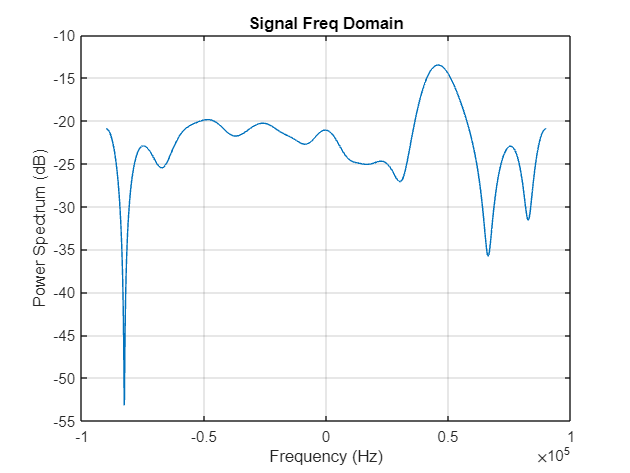

clear
Fs=180e3;
signal=randi([0 1],[4,10]);
ofdmsignal=ifft(signal,4);
timeSignal=reshape(ofdmsignal,[],1);

[pxx,f] = pspectrum(timeSignal,Fs);
plot(f,pow2db(pxx))
grid on
title('Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

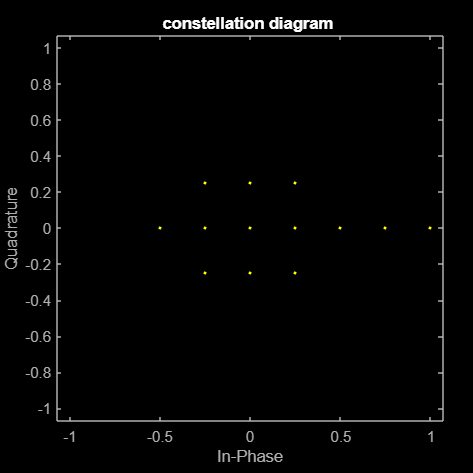


figure;
scatterplot(timeSignal);
title('constellation diagram ');


t = 0:1/Fs:(4*10/Fs)-1/Fs;
dopplerEffect = exp(1i * 2 * pi * 20e3* t);
dopplerSignal=transpose(timeSignal) .* (dopplerEffect);

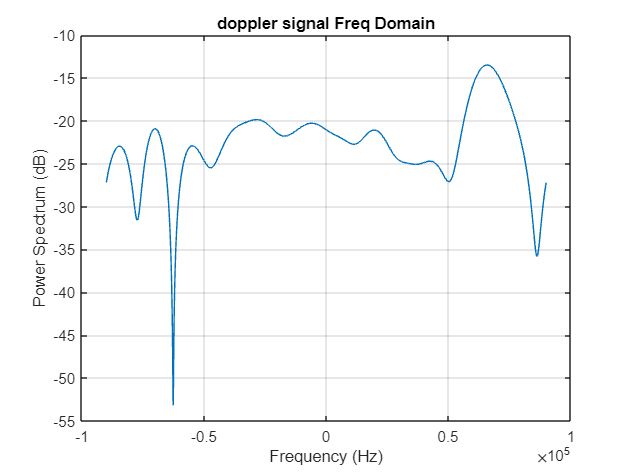

figure
[pxx2,f2] = pspectrum(dopplerSignal,Fs);
plot(f2,pow2db(pxx2))
grid on
title('doppler signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

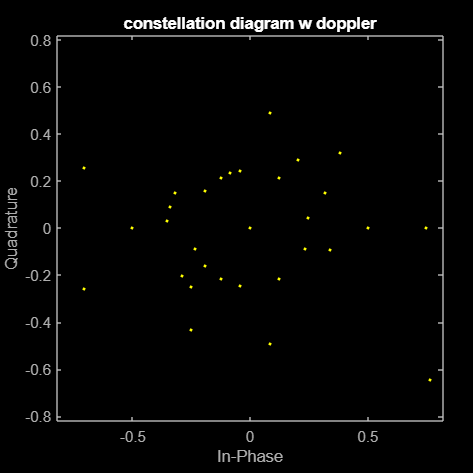


figure;
scatterplot(dopplerSignal);
title('constellation diagram w doppler');